# EKF Magnetometer Analysis

Daniel Pearson (12/1/2023)

## Introduction

The purpose of this script is to provide calibration data from the MMC5983 on Polaris V2.2 to be used in the orientation Extended Kalman Filter.

Magnetometers on their own provide little to know information about the system but can be a massive help in correcting error generated by the quaternion integration of the EKF prediction step.

## Method

This script will read data logged to a CSV file, filter and fit the data to an idealized system in order to provide the hard and soft data matrices to calibrate the system.

clear variables; close all; clc;

## Read CSV Data

csvLog = readtable('./polarisData.csv');

magX = csvLog.MagX;
magY = csvLog.MagY;
magZ = csvLog.MagZ;

## Apply Butterworth Filter

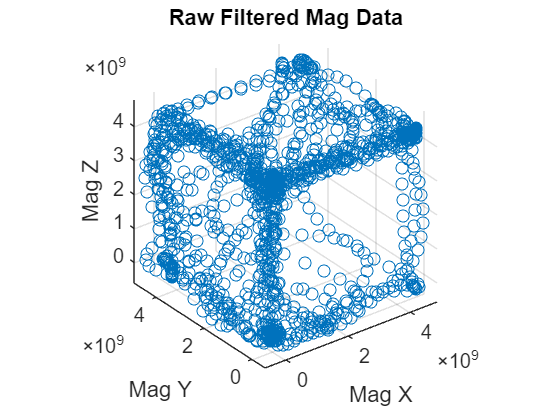

order = 4; % Filter Order
cutoffFreq = 0.1; % [Hz] Cutoff Frequency
[b_filt,a_filt] = butter(order, cutoffFreq);

filtered_magX = filtfilt(b_filt,a_filt, magX);
filtered_magY = filtfilt(b_filt,a_filt, magY);
filtered_magZ = filtfilt(b_filt,a_filt, magZ);

magEKFX = csvLog.MagCalX;
magEKFY = csvLog.MagCalY;
magEKFZ = csvLog.MagCalZ;

filtered_magEKFX = filtfilt(b_filt,a_filt, csvLog.MagCalX);
filtered_magEKFY = filtfilt(b_filt,a_filt, csvLog.MagCalY);
filtered_magEKFZ = filtfilt(b_filt,a_filt, csvLog.MagCalZ);

scatter3(filtered_magX, filtered_magY, filtered_magZ);
axis equal;
title('Raw Filtered Mag Data');
xlabel('Mag X');
ylabel('Mag Y');
zlabel('Mag Z');


scatter3(filtered_magEKFX, filtered_magEKFY, filtered_magEKFZ);

Unrecognized function or variable 'filtered_magEKFX'.

hold on;
% % Plot X-Y
% plot(filtered_magEKFX, filtered_magEKFY);
% axis equal;
% title('EKF Mag Data X-Y');
% xlabel('Mag X');
% ylabel('Mag Y');
% 
% % Plot X-Z
% plot(filtered_magEKFX, filtered_magEKFZ);
% axis equal;
% title('EKF Mag Data X-Z');
% xlabel('Mag X');
% ylabel('Mag Z');
% 
% % Plot Y-Z
% plot(filtered_magEKFY, filtered_magEKFZ);
% axis equal;
% title('EKF Mag Data Y-Z');
% xlabel('Mag Y');
% ylabel('Mag Z');

## Fit Plane to Calibrated Mag Readings

% Create a matrix A with columns corresponding to X, Y, and a column of ones
A = [filtered_magEKFX, filtered_magEKFY, ones(size(filtered_magEKFX))];

% Use the \ operator to solve the system of equations Ax = B, where B is the Z data
coefficients = A \ filtered_magEKFZ;

% Extract the coefficients for the plane equation: Z = a*X + b*Y + c
a = coefficients(1);
b = coefficients(2);
c = coefficients(3);

% Now you can plot the fitted plane along with your data
[X, Y] = meshgrid(min(filtered_magEKFX):0.01:max(filtered_magEKFX), min(filtered_magEKFY):0.01:max(filtered_magEKFY));
Z_fit = a*X + b*Y + c;

surf(X, Y, Z_fit, 'FaceAlpha', 0.5); % Plot the fitted plane
axis equal;
title('EKF Mag Data');
xlabel('Mag X');
ylabel('Mag Y');
zlabel('Mag Z');

## Calculate Angle Offset from X-Y Plane

centroid_X = mean(filtered_magEKFX);
centroid_Y = mean(filtered_magEKFY);
centroid_Z = mean(filtered_magEKFZ);

c = centroid_Z - a * centroid_X - b * centroid_Y;

Z_xyPlane = zeros(size(X)) + 0.6039;
surf(X, Y, Z_xyPlane, 'FaceAlpha', 0.5); % Plot the fitted plane
hold off;

N1 = [a;b;c];
N1 = N1/norm(N1);
N2 = [0;0;1];
N2 = N2/norm(N2);

angle = rad2deg(acos(dot(N1,N2)))